clc
%clear all
rng default % For reproducibility

## Humedad del producto


                              Average            Average
Generation   Func-count    Pareto distance    Pareto spread
    1            50

    3           150         0.0395855          0.955019
    4           200         0.0442223         0.0818418
    5           250         0.0310934         0.0747209
    6           300         0.0554543          0.132434
    7           350         0.0490019          0.107223
    8           400         0.0547877          0.140708
    9           450         0.0391964         0.0811623
   10           500         0.0368627          0.860244
   11           550         0.0313851         0.0664355
   12           600         0.0592534          0.107582
   13           650         0.0549066          0.497406
   14           700         0.0540359          0.104809
   15           750         0.0271373          0.052238
   16           800                 0                 1
   17           850                 0                 1
   18           900                 0                 0
   19           950                 0                 1
   20          1000                 0           

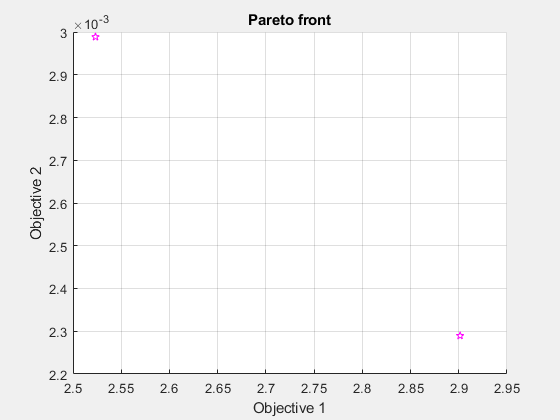

W0=200; % "Peso inicial del producto [kg]"100CHILE
m_i=0.87; % "Contenido inicial de humedad del producto en base húmeda"0.8
Mi=m_i/(1-m_i); % "Contenido inicial de humedad del producto en base seca"
mwi=W0*m_i; % "Contenido inicial de masa de agua"
md=mwi/Mi; % "masa de producto seco [kg]"
m_f=0.08; % "Contenido final de humedad en base húmeda"%0.223
m_des=0.1;%0.25
Mf=m_f/(1-m_f); % "Contenido final de humedad en base seca"
M_des=m_des/(1-m_des);
mwf=Mf*md; % "Masa final de agua [kg]"

%fun=@(O)opt_fun(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf);
% %A=[m_max T_min r_div2 t_rec_ini MR]
% A=[0 0 0 0 1]; %Valores del vector en la desigualdad
% b=[0.1]; %Restricción de desigualdad lineal
% ub=[0.4 60 0.99 30 1]; %Límite superior
% lb=[0.1 45 0.00 00 0]; %Límite inferior
%A=[m_max T_min r_div2 MR]

ub=[0.2 70 0.99 19]; %Límite superior
lb=[0.07 45 0.00 0]; %Límite inferior


load('final_pop_GLP100trec.mat')
popsz=50;
gen=20;
%%%options = optimoptions('gamultiobj','PopulationSize',popsz,'Generations', gen ...
%%%    ,'display','iter','PlotFcn',@gaplotpareto);%{@gaplotbestf, @gaplotbestindiv} );
options = optimoptions('gamultiobj','InitialPopulation',population,'PopulationSize',popsz,'Generations', gen ...
    ,'display','iter','PlotFcn',@gaplotpareto);%{@gaplotbestf, @gaplotbestindiv} );
%options = optimoptions('ga','ConstraintTolerance',1e-3,'CrossoverFraction',0.8,'EliteCount',1,'PopulationSize',4,'MaxGenerations',5);
%%%options = optimoptions('gamultiobj','PopulationSize',popsz,'Generations', gen ...
%%%    ,'display','iter','PlotFcn',@gaplotpare[x,fval,exitflag,output,population,scores]=gamultiobj(@(O)[opt_fun(O,W0,m_i,Mi, ...
%%%    mwi,md,m_f,m_des,Mf,M_des,mwf) opt_fun2(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des, ...
%%%    mwf) opt_fun3(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf)],3,[],[],[],[],lb,ub,options);
[x,fval,exitflag,output,population,scores]=gamultiobj(@(O)[opt_fun(O,W0,m_i,Mi, ...
     mwi,md,m_f,m_des,Mf,M_des,mwf) opt_fun2(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des, ...
     mwf) opt_fun3(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf)],4,[],[],[],[],lb,ub,options);

%[x,fval,exitflag,output,population,scores]=ga(@(O)opt_fun(O,W00,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf),4,A,b,[],[],lb,ub,[],[],options);


Estado original desde la última modificación al 20 09 2024

% W0=200; % "Peso inicial del producto [kg]"100CHILE
% m_i=0.87; % "Contenido inicial de humedad del producto en base húmeda"0.8
% Mi=m_i/(1-m_i); % "Contenido inicial de humedad del producto en base seca"
% mwi=W0*m_i; % "Contenido inicial de masa de agua"
% md=mwi/Mi; % "masa de producto seco [kg]"
% m_f=0.08; % "Contenido final de humedad en base húmeda"%0.223
% m_des=0.1;%0.25
% Mf=m_f/(1-m_f); % "Contenido final de humedad en base seca"
% M_des=m_des/(1-m_des);
% mwf=Mf*md; % "Masa final de agua [kg]"
% 
% %fun=@(O)opt_fun(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf);
% % %A=[m_max T_min r_div2 t_rec_ini MR]
% % A=[0 0 0 0 1]; %Valores del vector en la desigualdad
% % b=[0.1]; %Restricción de desigualdad lineal
% % ub=[0.4 60 0.99 30 1]; %Límite superior
% % lb=[0.1 45 0.00 00 0]; %Límite inferior
% %A=[m_max T_min r_div2 MR]
% 
% ub=[0.17 60 0.99]; %Límite superior
% lb=[0.07 45 0.00]; %Límite inferior
% 
% 
% load('final_pop200.mat')
% popsz=50;
% %options = optimoptions('gamultiobj','PopulationSize',popsz,'Generations', 10 ...
% %    ,'display','iter','PlotFcn',@gaplotpareto);%{@gaplotbestf, @gaplotbestindiv} );
% options = optimoptions('gamultiobj','InitialPopulation',final_pop,'PopulationSize',popsz,'Generations', 200 ...
%     ,'display','iter','PlotFcn',@gaplotpareto);%{@gaplotbestf, @gaplotbestindiv} );
% %options = optimoptions('ga','ConstraintTolerance',1e-3,'CrossoverFraction',0.8,'EliteCount',1,'PopulationSize',4,'MaxGenerations',5);
% 
% [x,fval,exitflag,output,population,scores]=gamultiobj(@(O)[opt_fun(O,W0,m_i,Mi, ...
%     mwi,md,m_f,m_des,Mf,M_des,mwf) opt_fun2(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des, ...
%     mwf) opt_fun3(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf)],3,[],[],[],[],lb,ub,options);
% %[x,fval,exitflag,output,population,scores]=ga(@(O)opt_fun(O,W0,m_i,Mi,mwi,md,m_f,m_des,Mf,M_des,mwf),4,A,b,[],[],lb,ub,[],[],options);
